# Create and Apply Windows

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/psdsig.mat
sig = 1e-3*sin(2*pi*fr*t);
n = length(sig);
w = ones(n, 1);

## Task 3-6

The rectangular window has the best frequency resolution among all windows. This comes is at the expense of spectral leakage.

Most windows can be created with functions that correspond to the window name. For example to make a Hamming window, you can use the `hamming` function.

`win` `=` `hamming``(``length``)`

In the time-domain plot, notice that the Hamming window attenuates the beginning and end of your signal. In the frequency-domain plot, compared to the rectangular window, there is better spectral leakage.

When you made the Hamming window, you only needed to set the window length. The Kaiser window also includes a shape factor called beta.

`win` `=` `kaiser``(``length``,``beta``)`

Larger beta values provide lower spectral leakage, at the expense of the frequency resolution. In the frequency-domain plot, pay attention to the height of the sidelobes before completing the next task.

w = hamming(n);
w = kaiser(n, 1);
w = kaiser(n, 6);
w = kaiser(n, 20);

## Task 1

In this activity, you'll create and visualize different windows. To start, a rectangular window has been created at the top of the script.

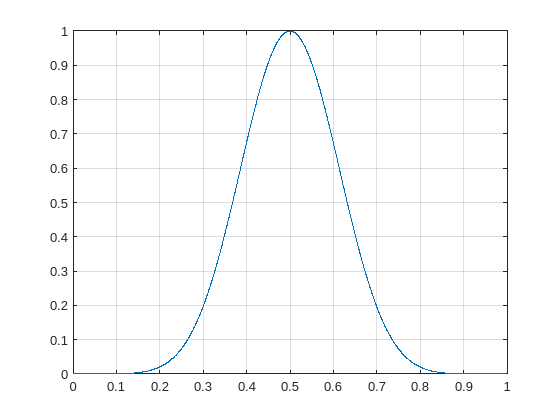

plot(t, w)
grid on

## Task 2

The time-domain plot shows that the rectangular window does not alter your signal.

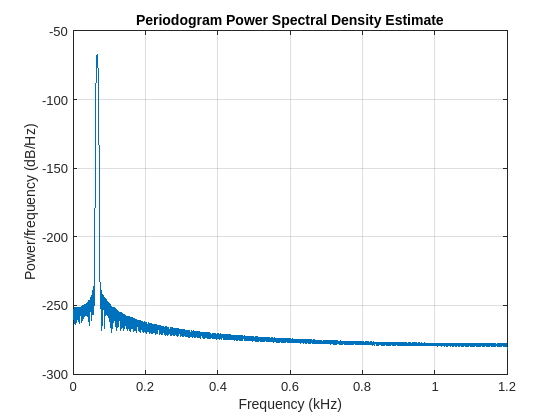

periodogram(sig, w, 2^12, fs);